close all
clear all
addpath 'C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\RL'
format bank
%rng(90)

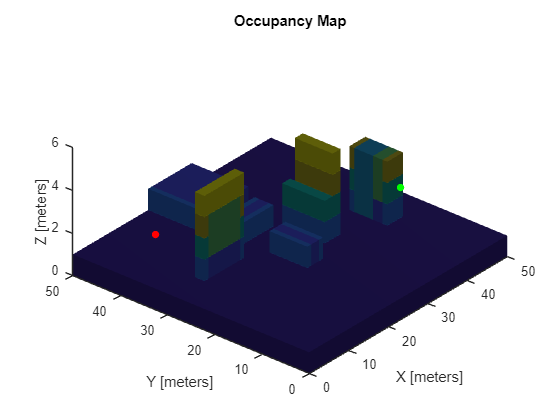

startPose = [47 27 2 pi/2];
goalPose = [10 5 2 pi/2];
MapNumber = 4;
if MapNumber == 1
    startPose = [47 27 2 pi/2];
    goalPose = [10 5 2 pi/2];
elseif MapNumber == 2
    startPose = [35 10 5 pi/2];
    goalPose = [5 45 2 pi/2];
elseif MapNumber == 3
    startPose = [12 6 3 pi/2];
    goalPose = [27 35 3 pi/2];
elseif MapNumber == 4
    startPose = [3 35 3 pi/2];
    goalPose = [35 10 4 pi/2];


end

mapData = load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\occupancy_map_3d"+MapNumber+".mat", 'omap3D');
MapOccupancy = mapData.omap3D;
occupancymapData = load("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\3D\map_data"+MapNumber+".mat");
MapData = occupancymapData.Map;

%MapData = gpuArray(MapData)

%El kellett forgatni 90 fokkal a térképet
MapData = permute(MapData, [2, 1, 3]);

%writematrix(MapData, "MapData" + 1 +".xlsx")



Env = RLEnv(MapData);
Env.RLAddEndSate(goalPose(1), goalPose(2), goalPose(3), 100);

figure("Name","StartAndGoal")
hMap = show(MapOccupancy);
hold on
scatter3(hMap,startPose(1),startPose(2),startPose(3),30,"red","filled")
scatter3(hMap,goalPose(1),goalPose(2),goalPose(3),30,"green","filled")
hold off
%view([90 90])

iteration = 50000;

xlim([0 50])
ylim([0 50])
zlim([0 6])

%Update Q_Table with Euclidean distance
EndCoordinates = [goalPose(1), goalPose(2), goalPose(3)];
tic
Env.RLAddManhatten(EndCoordinates)
Env.Q_Table;
toc

Elapsed time is 0.022494 seconds.


%Ez akkor ha üres térképet adunk meg.

%rng(80)
%Map setup
%Ez még nem általános minden magasságra, csak ami 3 emelet magas
% Env = RLEnv(10,10,4)
% MapOccupancy = occupancyMap3D;
% Env.RLAddObstacle(2,3,2,4,1,2,MapOccupancy)
% Env.RLAddObstacle(5,6,5,6,1,3,MapOccupancy)
% Env.RLAddObstacle(3,5,7,9,1,2,MapOccupancy)
% Env.RLAddEndSate(8, 8, 4, 100)
% show(MapOccupancy)


%Agent Setup
obsX = startPose(1);
obsY = startPose(2);
obsZ = startPose(3);
Agent = RLAgent(obsX, obsY, obsZ);
EndState = [goalPose(1) goalPose(2) goalPose(3)];
%RL Computations setup


%Itt a 0-át vissza kell írni
RL = RLClass(0.3, 0.8783, 0.9, EndState, Env.Q_Table)

RL =   RLClass with properties:

    LearningRate: 0.30
           Gamma: 0.88
         epsilon: 0.90
        EndState: [35.00 10.00 4.00]
         Q_Table: [50×50×5 double]


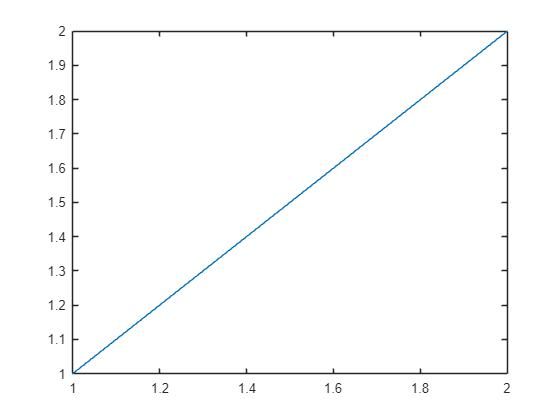

%Setup the Required Datas
ExistingData = [];
Steps = [];
StepsWFail = [];
All_cost = [1;2];
All_costWFail = [];
y = All_cost;
FinalRoute = [];
f2 = figure('Name','Cost Data');
figure(f2);
x = 1:size(All_cost);
p=plot(x,y);

p.XDataSource="x";
p.YDataSource="y";
c = 1;


%Train the algorithm
tic
for k=1:iteration
    if rem(k, 1000) == 0
        iteracio = k + ". iteráció";
        toc
        disp(iteracio)
    end
    %user = memory;
    %disp(user.MemUsedMATLAB/1000000)
    costValue = 0;
    i = 0;
    Agent.RLReset();
    Agent.AgentState;
    obsX =  Agent.AgentState(1);
    obsY =  Agent.AgentState(2);
    obsZ =  Agent.AgentState(3);
    ExistingData = [];
    while true
        i;
        if size(ExistingData,1) > 15000
            break
        end

        [next_state, reward, done, ExistingData, Goal] = RL.lepes(obsX, obsY, obsZ, Agent.AgentState, ExistingData);
        
        [cost, Q_Table] = RL.learn(obsX, obsY, obsZ, reward, next_state);
        costValue = costValue + cost;
        
        obsX = next_state(1);
        obsY = next_state(2);
        obsZ = next_state(3);
        Agent.AgentState = next_state;
        i = i+1;
        
        if done == 1 || done == -1
            if done == 1
                c = c+1;
                Steps = [Steps; i];
                All_cost = [All_cost;costValue];
            end
            %StepsWFail = [StepsWFail; i];
            %All_costWFail = [All_costWFail;costValue];
            break
        end
    end
    
    %Itt majd még meg kell különböztetni azt a lehetőséget amikor amiatt
    %lett vége mert elérte a célt, illetve azt amikor amiatt lett vége
    %mert akaádlyba ütközött
    if isempty(FinalRoute) && Goal
        FinalRoute = ExistingData;
    elseif size(ExistingData,1) < size(FinalRoute, 1) && Goal
        FinalRoute = ExistingData;
    end
    
end

Elapsed time is 3.408784 seconds.


1000. iteráció


Elapsed time is 6.289057 seconds.


2000. iteráció


Elapsed time is 8.088930 seconds.


3000. iteráció


Elapsed time is 9.757389 seconds.


4000. iteráció


Elapsed time is 11.223981 seconds.


5000. iteráció


Elapsed time is 12.645425 seconds.


6000. iteráció


Elapsed time is 14.668713 seconds.


7000. iteráció


Elapsed time is 16.459257 seconds.


8000. iteráció


Elapsed time is 18.034905 seconds.


9000. iteráció


Elapsed time is 19.895162 seconds.


10000. iteráció


Elapsed time is 21.614968 seconds.


11000. iteráció


Elapsed time is 23.209829 seconds.


12000. iteráció


Elapsed time is 24.630288 seconds.


13000. iteráció


Elapsed time is 26.167019 seconds.


14000. iteráció


Elapsed time is 27.801521 seconds.


15000. iteráció


Elapsed time is 29.288641 seconds.


16000. iteráció


Elapsed time is 31.083399 seconds.


17000. iteráció


Elapsed time is 32.396610 seconds.


18000. iteráció


Elapsed time is 33.820355 seconds.


19000. iteráció


Elapsed time is 35.247559 seconds.


20000. iteráció


Elapsed time is 37.032728 seconds.


21000. iteráció


Elapsed time is 38.465364 seconds.


22000. iteráció


Elapsed time is 39.771085 seconds.


23000. iteráció


Elapsed time is 41.234007 seconds.


24000. iteráció


Elapsed time is 42.602647 seconds.


25000. iteráció


Elapsed time is 44.228395 seconds.


26000. iteráció


Elapsed time is 45.560649 seconds.


27000. iteráció


Elapsed time is 47.084879 seconds.


28000. iteráció


Elapsed time is 48.474750 seconds.


29000. iteráció


Elapsed time is 49.872581 seconds.


30000. iteráció


Elapsed time is 51.304874 seconds.


31000. iteráció


Elapsed time is 52.798004 seconds.


32000. iteráció


Elapsed time is 54.533604 seconds.


33000. iteráció


Elapsed time is 56.167850 seconds.


34000. iteráció


Elapsed time is 57.638983 seconds.


35000. iteráció


Elapsed time is 59.481445 seconds.


36000. iteráció


Elapsed time is 61.048772 seconds.


37000. iteráció


Elapsed time is 62.505003 seconds.


38000. iteráció


Elapsed time is 63.800259 seconds.


39000. iteráció


Elapsed time is 65.099372 seconds.


40000. iteráció


Elapsed time is 66.423011 seconds.


41000. iteráció


Elapsed time is 67.713140 seconds.


42000. iteráció


Elapsed time is 69.259470 seconds.


43000. iteráció


Elapsed time is 70.824560 seconds.


44000. iteráció


Elapsed time is 72.782189 seconds.


45000. iteráció


Elapsed time is 74.407343 seconds.


46000. iteráció


Elapsed time is 75.947583 seconds.


47000. iteráció


Elapsed time is 77.523025 seconds.


48000. iteráció


Elapsed time is 79.200619 seconds.


49000. iteráció


Elapsed time is 80.517513 seconds.


50000. iteráció


toc

Elapsed time is 80.524811 seconds.


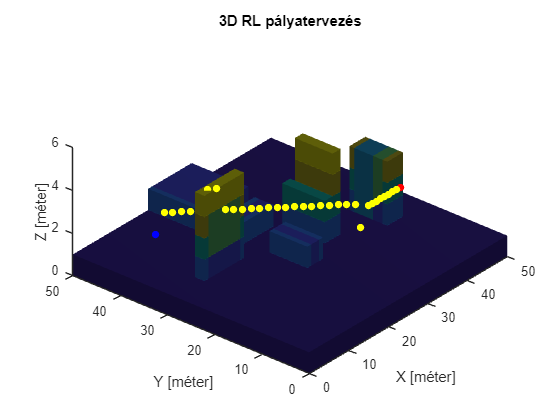


%Plot the Data
f4 = figure('Name','QAgent is learning');
figure(f4);
show(MapOccupancy)
hold on

scatter3(startPose(1),startPose(2),startPose(3),30,"blue","filled")
scatter3(FinalRoute(:,1),FinalRoute(:,2),FinalRoute(:,3),30,"yellow","filled")
scatter3(goalPose(1),goalPose(2),goalPose(3),30,"red","filled")
xlim([0 50])
ylim([0 50])
zlim([0 6])
title("3D RL pályatervezés")
xlabel("X [méter]")
ylabel("Y [méter]")
zlabel("Z [méter]")

%Plot the Cost Data
f2 = figure('Name','Cost Data');
figure(f2);
x = 1:size(All_cost)

x =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00         11.00         12.00         13.00         14.00         15.00         16.00         17.00         18.00         19.00         20.00         21.00         22.00         23.00         24.00         25.00         26.00         27.00         28.00         29.00         30.00         31.00         32.00         33.00         34.00         35.00         36.00         37.00         38.00         39.00         40.00         41.00         42.00         43.00         44.00         45.00         46.00         47.00         48.00         49.00         50.00


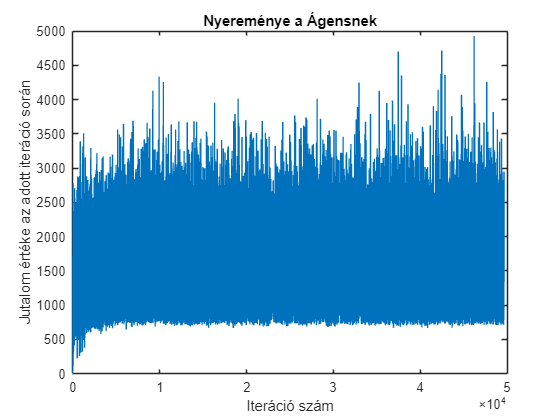

plot(x,All_cost)
title("Nyereménye a Ágensnek")
xlabel("Iteráció szám")
ylabel("Jutalom értéke az adott iteráció során")

%ylim([-5000 2000])
Q_Table

Q_Table = Q_Table(:,:,1) =

         -0.43         -0.39         -0.40         -0.41         -0.45         -0.42         -0.44         -0.40         -0.43         -0.46         -0.48         -0.45         -0.49         -0.52         -0.57         -0.60         -0.58         -0.61         -0.65         -0.69         -0.74         -0.79         -0.82         -0.86         -0.91         -0.97         -1.02         -1.08         -1.13         -1.18         -1.22         -1.25         -1.28         -1.24         -1.30         -1.22         -1.25         -1.26         -1.25         -1.22         -1.21         -1.19         -1.17         -1.19         -1.18         -1.17         -1.17         -1.17         -1.16         -1.17
         -0.38         -0.41         -0.43         -0.41         -0.40         -0.41         -0.42         -0.46         -0.44         -0.43         -0.44         -0.48         -0.52         -0.54         -0.55         -0.56         -0.57         -0.62         -0.64     

%Plot the Step Data
f3 = figure('Name','Step Data');
figure(f3);
x = 1:size(Steps)

x =           1.00          2.00          3.00          4.00          5.00          6.00          7.00          8.00          9.00         10.00         11.00         12.00         13.00         14.00         15.00         16.00         17.00         18.00         19.00         20.00         21.00         22.00         23.00         24.00         25.00         26.00         27.00         28.00         29.00         30.00         31.00         32.00         33.00         34.00         35.00         36.00         37.00         38.00         39.00         40.00         41.00         42.00         43.00         44.00         45.00         46.00         47.00         48.00         49.00         50.00


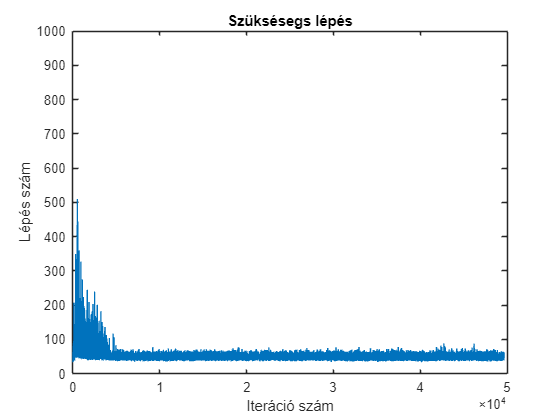

plot(x,Steps)
title("Szüksésegs lépés")
xlabel("Iteráció szám")
ylabel("Lépés szám")
ylim([0 1000])

%Save the corresponding Path
save("3D\RLVFH\MapFinal_" + MapNumber+".mat", "FinalRoute")